% Lab 1 for Digital Audio Signal Processing Lab Sessions
% Exercise 1-4: 3D audio
%
% In this lab, we derive a set of filters g that can be used, along with
% the measured RIRs H, to produce the proper psychocoustic rendition of 3D
% audio
%
%

clear;
close all

if ispc
    addpath('..\..\audio_files');
    addpath('..\..\sim_environment');
else
    addpath('../../audio_files');
    addpath('../../sim_environment');
end

% Load ATFs
load Computed_RIRs

% Load measured HRTFs
load HRTF

% Define the signal length
siglength = 10;

% Load the speech signal and resample
source_filename{1} = 'speech1.wav';
% ---------play with them!---------
% Noise flag for the noise perturbing SOE
noiseFlag = false;
% Noise flag for sweetspot tests
sweetspotFlag = false;
% one-tap defined HRTF or loaded HRTF
onetap = false;

% Number of loudspeakers
J = size(RIR_sources,3);

% Define the lengths of RIRs and g filters
Lh = 168; % Length of impulse responses of listeniLg room
Lg = 400;      % Length of filters g_j

% Truncate impulse response to reduce computational complexity

% Calculate delay(samples) for SOE
Delta = ceil(sqrt(room_dim(1)^2 + room_dim(2)^2)*fs_RIR/340);

% Define the Toeplitz matrices for left and right ear (left side of SOE)
[HL,HR] = getHByRIR(RIR_sources,Lh,Lg); 
% Define the HRTFs for left and right ear (right side of SOE) from the

if(onetap)
    % one-tap HRTF
    xL = zeros(Lg+Lh-1,1); % Left ear
    xR = zeros(Lg+Lh-1,1); % Right ear
    xL(Delta+1) = 3;
    xR(Delta+1) = 3; %？ front source 1
else
    % load HRTF
    xL = [zeros(Delta,1);HRTF(1:Lg+Lh-1-Delta,1)];
    xR = [zeros(Delta,1);HRTF(1:Lg+Lh-1-Delta,2)];
end


## SOE

% Construct H (from HL and HR) and x (from xL and xR) and remove all-zero rows in H, and the corresponding elements in x
binaural_length_left = sum(any(HL,2),1);
binaural_length_right = sum(any(HR,2),1);
binaural_length = min(binaural_length_right,binaural_length_left);

x = [xL;xR];
H = [HL;HR];
% remove zeros
x = x(any(H,2));
H = H(any(H,2),:);

% Solve the SOE
if ~noiseFlag
    % Without noise
    g = H\x;
else
    % With noise
    estimation_error = 0.05;
    H_with_noise = estimation_error*std(H(:,1))*randn(size(H,1),size(H,2))+H;
    g = H_with_noise\x;
end

HRTF_esti = H*g;
HRTF_esti_binaural = [HRTF_esti(1:binaural_length) HRTF_esti(binaural_length_left+1:binaural_length_left+binaural_length)];

## Plot estimated and real HRTFs

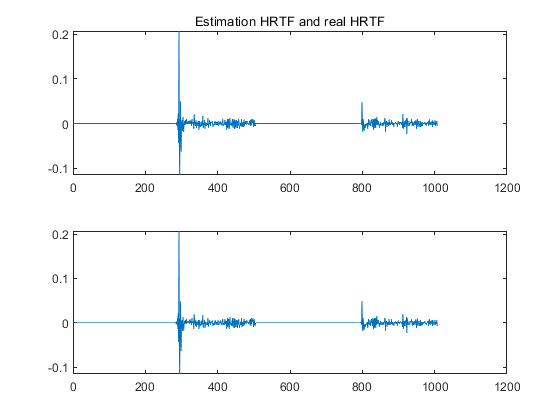

figure(1); clf;
subplot(2,1,1);
plot(HRTF_esti);
title('Estimation HRTF and real HRTF')
subplot(2,1,2);
plot(x);

% Calculate synthesis error
synth_error = norm(HRTF_esti-x)

synth_error = 1.0640e-11

## Synthethize the binaural speech using H and g and compare it

[source_signals_raw{1}, source_signals_raw{2}] = audioread(source_filename{1});
y  = resample(source_signals_raw{1},fs_RIR,source_signals_raw{2});
y = y(1:siglength*fs_RIR);


binaural_sig = fftfilt(HRTF_esti_binaural,y);
%binaural_sig = fftfilt(HRTF,y);
save ('binaural_sig_non_reveb','binaural_sig','siglength');

%soundsc(binaural_sig,fs_RIR)
% (psychoacoustically) to the binaural speech synthetized with x

% HRTF_binaural = reshape(HRTF,length(HRTF)/2,2);
% binaural_sig = fftfilt([xL,xR],y);
soundsc(binaural_sig,fs_RIR);

if(sweetspotFlag)
    isCorrect = isSweetSpot(y,m_pos,s_pos,v_pos,room_dim,rev_time,fs_RIR,size(RIR_sources,1),Lh,Lg,g);
end

## Util Functions

function isSweetSpot = isSweetSpot(y,m_pos,s_pos,v_pos,room_dim,rev_time,fs_RIR,RIR_length,Lh,Lg,g)
% Assume speakers are located on the RHS of the listener. To maximize the
% distortion, we need to move the mics 5cm rightward, corresponse to (x,y) --> (x,y-0.05)
m_pos_new = m_pos;
m_pos_new(:,2) = m_pos(:,2)-0.05; % move the mics 5cm rightward
% after generating the new impulse response, we calculate the corresponding
% HRTF for the original calculated g.
cd temp % avoid saving Computed_RIRs.mat 
[RIR_sources_new,~] = create_rirs(m_pos_new,s_pos,v_pos,room_dim,rev_time,fs_RIR,RIR_length);
cd ..
[HL_new,HR_new] = getHByRIR(RIR_sources_new,Lh,Lg);
H_new = [HL_new;HR_new];
HRTF =H_new*g;
HRTF_binaural = reshape(HRTF,length(HRTF)/2,2);
% there are two ways to test if the 3D effect is still correct:

% 1. simulate the heared signal. judge it objectively.
HRTF_binaural = reshape(HRTF,length(HRTF)/2,2);
binaural_sig = fftfilt(HRTF_binaural,y);
soundsc(binaural_sig);

% 2. test the peaks of the HRTF still have 2 or more delay.
[amplitude,peaks] = max(HRTF_binaural);
isSweetSpot = abs(peaks(2)-peaks(1)) >= 2 && abs(peaks(2)-peaks(1))<=20 %% test amplitude of HRTF LHS and RHS,max L < max R

% override the new generated Computed_RIRs.mat

end

function [HL,HR] = getHByRIR(RIR_sources,Lh,Lg)
% RIR_sources: (RIR_length,mics,sources)
HL_pre = squeeze(RIR_sources(1:Lh,1,:));
HR_pre = squeeze(RIR_sources(1:Lh,2,:));
HL = createAndMergeToplitzMatrix(HL_pre,Lg);
HR = createAndMergeToplitzMatrix(HR_pre,Lg);
end

function [T] = createAndMergeToplitzMatrix(H,Lg)
% H: (Lh x J)matrix.
% Lg: Lg
% output: (Lh+Lg-1,Lg*J) toplitz matrixL
Lh = size(H,1);
J = size(H,2);
T = zeros(Lh+Lg-1,Lg*J);
for j=1:J
    T(:,Lg*(j-1)+1:Lg*j) = createToplitz(H(:,j),Lg);
end
end

function [T] = createToplitz(H,Lg)
% H: (Lh x 1)vector. HL(:,i) in this case(corresponse to ith sources)
% Lg: Lg
% output: (Lh+Lg-1,Lg) toplitz matrix
a = [H;zeros(Lg-1,1)];
c = [a(1);zeros(Lg-1,1)];%%change b to a
T = toeplitz(a,c);
end


## Questions

%1-4 ------------------
%q3: signals generated from source then propogated to listenrs have delay,
% depend on room size and sound velocity, add zeros before XR(t) and XL(t)
%q5: removal of all zeros influence g(i), if i th row of H is all zero,
%x(i) is infinate, then g(i)would be NAN, it's not realistic 
%q8: get similar effect by using HRTF and HRTF_esti
%q9: can. if all mics are on the left, all HL > HR, we need to generate
%virtual RHS source that HRTF(R)>HRFT(L) as long as g(i) is negetive
%q10 : move 2 mics(ears) along y by 5cm and see if the delay samples of max peak
%still exist,but there is a controdict about amplification...
%11: whiht noise and deviation affect bineural signal significantly, almost
%destory the 3d signal, and can hardly mimic HRTF 